# Check fastICA on random signals 

create matrix with 50 cells and 100 time points, with 3 source signals 

%% random combination of signals of 3 sources
N=100; %data size
v=[0:N-1];
sig=[];
sig(1,:)=sin(v/2); %sinusoid
sig(2,:)=sin(v/5); %sinusoid
sig(3,:)=cos(v/2); %sinusoid
% sig(2,:)=((rem(v,23)-11)/9).^5; %funny curve
% sig(3,:)=((rem(v,27)-13)/9); %saw-tooth
sig(4,:)=((rand(1,N)<.5)*2-1).*log(rand(1,N)); %impulsive noise
coef=[10*rand(1,8),rand(1,42);
rand(1,15),10*rand(1,5),rand(1,30);
rand(1,25),10*rand(1,5),rand(1,20);
rand(1,44),10*rand(1,6)];
% signal=sig'*coef;
signal=sig'*coef+0.001*(rand(100,50)-0.5); % -> see if some noise are added the results
% will be different 

## run fastica

[ic, A, W] = fastica(signal','numOfIC',4);

Number of signals: 50
Number of samples: 100
Calculating covariance...
Dimension reduced to 19 due to the singularity of covariance matrix
Selected [ 19 ] dimensions.
Smallest remaining (non-zero) eigenvalue [ 1.00395e-07 ]
Largest remaining (non-zero) eigenvalue [ 372.896 ]
Sum of removed eigenvalues [ 1.50908e-06 ]
[ 100 ] % of (non-zero) eigenvalues retained.
Whitening...
Check: covariance differs from identity by [ 1.60076e-07 ].
Used approach [ defl ].
Used nonlinearity [ pow3 ].
Starting ICA calculation...
IC 1 ..............computed ( 14 steps ) 
IC 2 .....................................computed ( 37 steps ) 
IC 3 ..................................computed ( 34 steps ) 
IC 4 ............computed ( 12 steps ) 
Done.
Adding the mean back to the data.


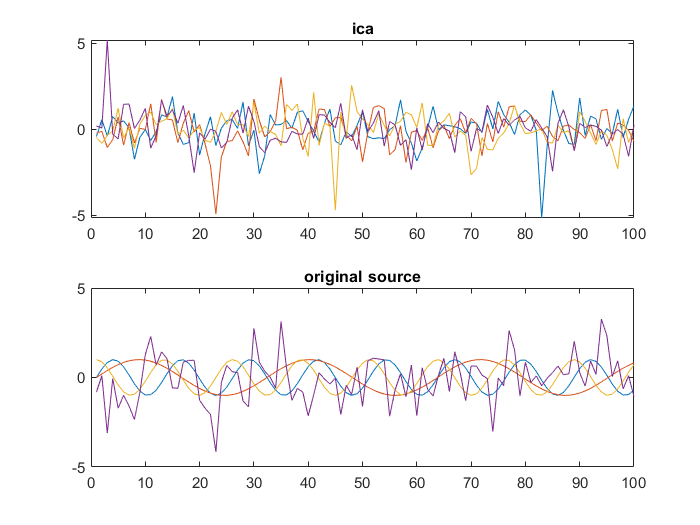

% ic=W*input; W = components x weights on cell
%% plot sources and ics
figure
subplot(2,1,1)
plot(ic')
title('ica')
subplot(2,1,2)
plot(sig')
title('original source')

corr(ic',sig')

ans =     0.0247    0.1471    0.2767    0.0527
    0.2027    0.2599   -0.0337    0.6560
    0.0366   -0.1432    0.2708    0.0427
    0.2515    0.1942    0.2057   -0.3094


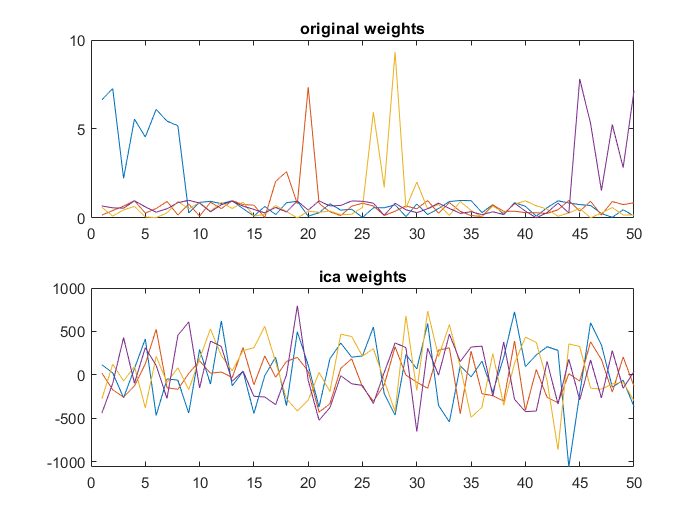

%% check weights on cells
figure
subplot(2,1,1)
plot(coef')
title('original weights')
subplot(2,1,2)
plot(W')
title('ica weights')

corr(coef',W')

ans =    -0.0609    0.0432   -0.1104   -0.0160
   -0.0617    0.0437   -0.1118   -0.0162
   -0.0453    0.0321   -0.0821   -0.0119
   -0.0582    0.0412   -0.1055   -0.0153
